clear; clc; close all;
%% 1) SETTINGS
Fs = 1000;                  % Sampling frequency (Hz)
sigDuration = 1;            % seconds per signal example
t = 0 : 1/Fs : sigDuration - 1/Fs;
N = length(t);
SNR_levels = [20 10 5 0];   % dB, as given in the project
examplesPerLevel = 150;     % how many noisy examples to generate per SNR level

%% 2) GENERATE DATASET: Signal -> Noise -> DSP Features
% For each SNR level, generate many different "clean" signals (varying
% frequency/amplitude/phase so the ANN doesn't just memorize one shape),
% add noise at that exact SNR, then compute DSP features from the
% noisy signal. Features are the ANN's input; true SNR is the target.
numFeatures = 8;
totalExamples = length(SNR_levels) * examplesPerLevel;
X = zeros(numFeatures, totalExamples);   % feature matrix
Y = zeros(1, totalExamples);             % target SNR values
col = 0;
for s = 1:length(SNR_levels)
    SNR_dB = SNR_levels(s);
    for k = 1:examplesPerLevel
        col = col + 1;
        % --- Generate a random "clean" signal (sum of 2 sinusoids) ---
        f1 = 20 + 30*rand();          % random frequency 1 (20-50 Hz)
        f2 = 60 + 80*rand();          % random frequency 2 (60-140 Hz)
        a1 = 0.7 + 0.6*rand();        % random amplitude 1
        a2 = 0.3 + 0.4*rand();        % random amplitude 2
        cleanSig = a1*sin(2*pi*f1*t) + a2*sin(2*pi*f2*t);
        % --- Add noise at the target SNR (manual, no toolbox needed) ---
        signalPower = mean(cleanSig.^2);
        snrLinear = 10^(SNR_dB/10);
        noisePower = signalPower / snrLinear;
        noise = sqrt(noisePower) * randn(1, N);
        noisySig = cleanSig + noise;
        % --- Extract DSP features from the noisy signal ---
        % 1. RMS (overall signal magnitude)
        rmsVal = sqrt(mean(noisySig.^2));
        % 2. Variance
        varVal = var(noisySig);
        % 3. Zero-crossing rate
        zcr = sum(abs(diff(sign(noisySig)))) / (2*N);
        % 4. Mean absolute value
        mav = mean(abs(noisySig));
        % 5. Crest factor (peak-to-RMS ratio)
        crestFactor = max(abs(noisySig)) / rmsVal;
        % 6. Kurtosis (how "peaky"/impulsive the signal is)
        kurtVal = kurtosis(noisySig);
        % 7 & 8. Spectral features via FFT
        Yf = abs(fft(noisySig));
        Yf = Yf(1:floor(N/2));
        freqAxis = (0:floor(N/2)-1) * (Fs/N);
        % Spectral centroid (center of mass of the spectrum)
        spectralCentroid = sum(freqAxis .* Yf) / sum(Yf);
        % High-frequency energy ratio (proxy for noise level -- noise
        % spreads energy across all frequencies, raising the high-freq
        % share relative to a clean tonal signal)
        lowBand = freqAxis <= 150;
        highBand = freqAxis > 150;
        highFreqRatio = sum(Yf(highBand).^2) / sum(Yf(lowBand).^2 + eps);
        % --- Store feature vector and target ---
        X(:, col) = [rmsVal; varVal; zcr; mav; crestFactor; ...
                     kurtVal; spectralCentroid; highFreqRatio];
        Y(col) = SNR_dB;
    end
end
fprintf('Generated %d examples (%d per SNR level: %s dB)\n', ...
    totalExamples, examplesPerLevel, mat2str(SNR_levels));

Generated 600 examples (150 per SNR level: [20 10 5 0] dB)


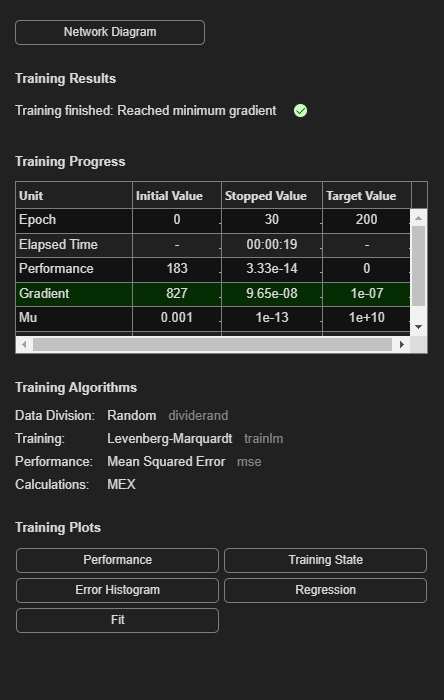


%% 3) NORMALIZE FEATURES
% Neural networks train much better when inputs are on similar scales.
Xmean = mean(X, 2);
Xstd = std(X, 0, 2);
Xnorm = (X - Xmean) ./ Xstd;

%% 4) SHUFFLE AND SPLIT INTO TRAIN / TEST
rng(1);   % for reproducibility
shuffleIdx = randperm(totalExamples);
Xnorm = Xnorm(:, shuffleIdx);
Y = Y(shuffleIdx);
trainRatio = 0.8;
numTrain = round(trainRatio * totalExamples);
XTrain = Xnorm(:, 1:numTrain);
YTrain = Y(1:numTrain);
XTest = Xnorm(:, numTrain+1:end);
YTest = Y(numTrain+1:end);

%% 5) BUILD AND TRAIN THE ANN (regression network)
% fitnet is MATLAB's standard feedforward network for regression
% (predicting a continuous number rather than a class label).
hiddenLayerSizes = [16 8];
net = fitnet(hiddenLayerSizes);
net.divideParam.trainRatio = 0.85;
net.divideParam.valRatio = 0.15;
net.divideParam.testRatio = 0;
net.trainParam.epochs = 200;
net.trainParam.showWindow = true;
[net, tr] = train(net, XTrain, YTrain);


%% 6) EVALUATE ON TEST SET
YPred = net(XTest);
rmse = sqrt(mean((YPred - YTest).^2));
mae = mean(abs(YPred - YTest));
fprintf('Test RMSE: %.2f dB\n', rmse);

Test RMSE: 0.00 dB


fprintf('Test MAE:  %.2f dB\n', mae);

Test MAE:  0.00 dB


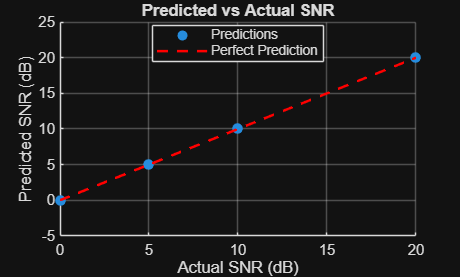


%% 7) VISUALIZE RESULTS
% Predicted vs Actual SNR scatter plot
figure;
scatter(YTest, YPred, 40, 'filled'); hold on;
plot([min(SNR_levels) max(SNR_levels)], [min(SNR_levels) max(SNR_levels)], ...
    'r--', 'LineWidth', 1.5);
xlabel('Actual SNR (dB)'); ylabel('Predicted SNR (dB)');
title('Predicted vs Actual SNR');
legend('Predictions', 'Perfect Prediction', 'Location', 'best');
grid on;

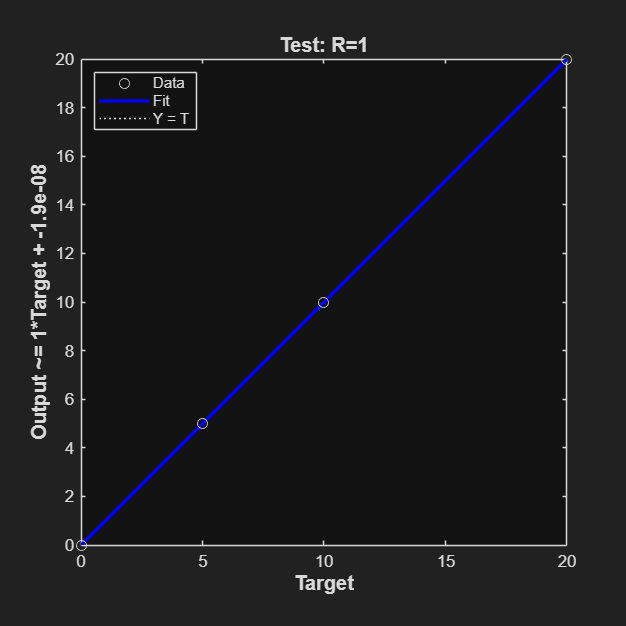

% Regression plot (built-in MATLAB tool)
figure;
plotregression(YTest, YPred, 'Test');

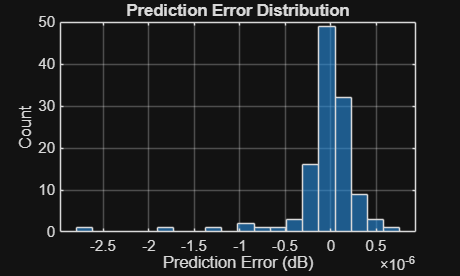

% Error distribution
figure;
histogram(YPred - YTest, 20);
xlabel('Prediction Error (dB)'); ylabel('Count');
title('Prediction Error Distribution');
grid on;

%% ================================================================
%  DONE
% ================================================================
disp('SNR prediction complete.');

SNR prediction complete.
